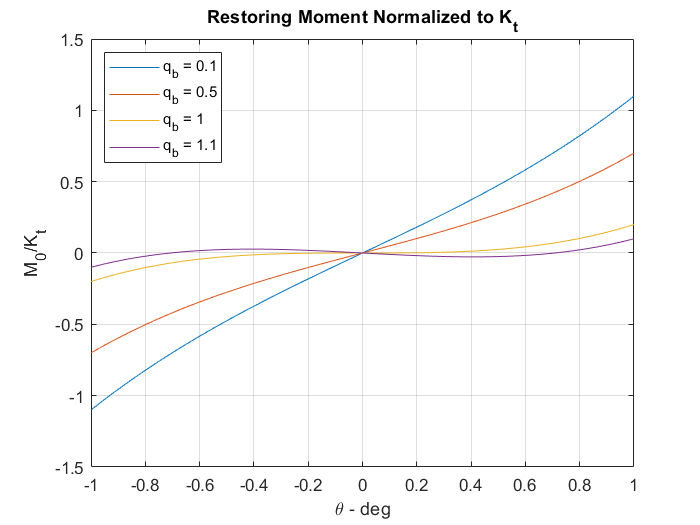

clc
clear all
%% Part - b
theta = linspace(-1,1,1000);
q_b = [0.1 0.5 1 1.1];
y_1 = (1 - q_b(1)).*theta + 0.2.*(theta).^3;
y_2 = (1 - q_b(2)).*theta + 0.2.*(theta).^3;
y_3 = (1 - q_b(3)).*theta + 0.2.*(theta).^3;
y_4 = (1 - q_b(4)).*theta + 0.2.*(theta).^3;

plot(theta,y_1,'DisplayName','q_b = 0.1')
hold on
plot(theta,y_2,'DisplayName','q_b = 0.5')
plot(theta,y_3,'DisplayName','q_b = 1')
plot(theta,y_4,'DisplayName','q_b = 1.1')
legend('Location',"northwest")
xlabel('\theta - deg')
ylabel('M_0/K_t')
title('Restoring Moment Normalized to K_t')
grid on
hold off

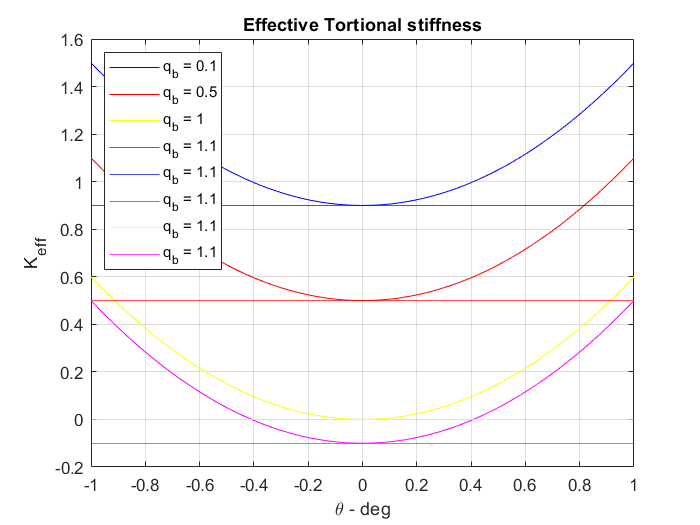

%% Part c
Keffl_1 = (1 - q_b(1));
Keffl_2 = (1 - q_b(2));
Keffl_3 = (1 - q_b(3));
Keffl_4 = (1 - q_b(4));
Keff_1 = (1 - q_b(1)) + 0.6.*(theta).^2;
Keff_2 = (1 - q_b(2)) + 0.6.*(theta).^2;
Keff_3 = (1 - q_b(3)) + 0.6.*(theta).^2;
Keff_4 = (1 - q_b(4)) + 0.6.*(theta).^2;
plot(theta,Keff_1,'DisplayName','q_b = 0.1',"Color",'blue')
hold on
plot(theta,Keff_2,'DisplayName','q_b = 0.5','Color','red')
plot(theta,Keff_3,'DisplayName','q_b = 1',"Color",'yellow')
plot(theta,Keff_4,'DisplayName','q_b = 1.1',"Color",'magenta')
yline(Keffl_1,'DisplayName','q_b = 1.1',"Color",'blue')
yline(Keffl_2,'DisplayName','q_b = 1.1','Color','red')
yline(Keffl_3,'DisplayName','q_b = 1.1',"Color",'yellow')
yline(Keffl_4,'DisplayName','q_b = 1.1',"Color",'magenta')
legend('Location','northwest')
xlabel('\theta - deg')
ylabel('K_e_f_f')
title('Effective Tortional stiffness')
grid on
hold off